# Trying to generate PSRN and SAM

12/1/2022

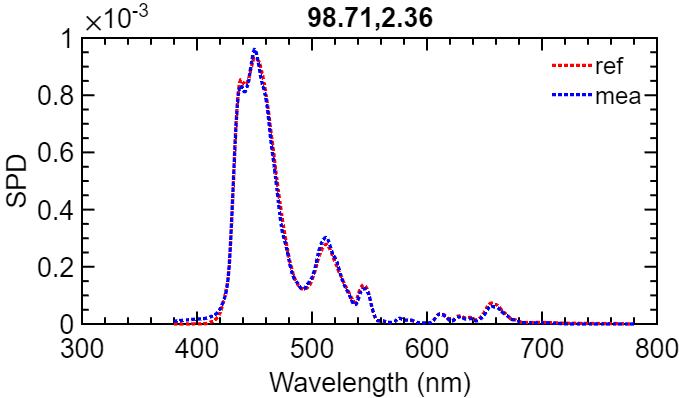

ans = 'done'

ans = 'done'

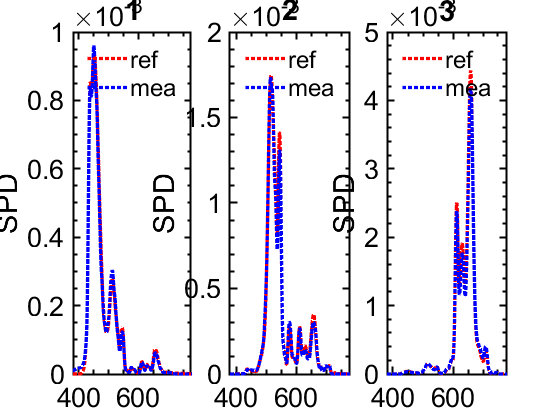

ans = 'done'



analyze_one_display('compare_RGB_primaries_result_nec','NEC')

%analyze_one_display('compare_RGB_primaries_result_hp','HP')
%analyze_one_display('compare_RGB_primaries_result_rift','RIFT')



function analyze_one_display_old (fn_mat, dispname)
load(fn_mat)
nexttile; compare_psnr_sam(s_predicted_b,mea_b,'b'); ylabel(dispname)
nexttile; compare_psnr_sam(s_predicted_g,mea_g,'g');
nexttile; compare_psnr_sam(s_predicted_r,mea_r,'r');
end

function analyze_one_display (fn_mat, dispname)
load(fn_mat)
clf
compare_psnr_sam(s_predicted_b,mea_b,1);

hfig = figure;
set(hfig, 'Units', 'inches', ...
    'Color', [1,1,1]);

my_compare_psnr_sam(s_predicted_b,mea_b,1);
my_compare_psnr_sam(s_predicted_g,mea_g,2);
my_compare_psnr_sam(s_predicted_r,mea_r,3);

end

%%
function [psnr_val sam_deg] = my_compare_psnr_sam (speC1, speC2, no)


s1 = speC1.amplitude;
s2 = speC2.amplitude;
psnr_val = psnr(s1,s2);
sam_deg = rad2deg(sam(s1,s2));

s1 = speC1.amplitude;
s2 = speC2.amplitude;

haxis = subplot(1,3,no);
% set(haxis, ...
%     'Units'              , 'Normalized',...
%     'Position'           , [(no-1)/3, 0, 1/3, 1]);
hold on
plot(380:780,s1,'r:')
plot(380:780,s2,'b:')
%axis([380 780 0 5e-3])
tstr = sprintf('%.2f, %.2f',psnr_val,sam_deg);
title(no)
xlabel('Wavelength (nm)')
ylabel('SPD')
legend('ref','mea')

beautify(haxis);
'done'
end

function beautify (haxis)
FontName = 'Arial';
FontSize = 20;

hp = get(haxis, 'Children');
N = length(hp);
LineWidth = 2.5*ones(1, N);
LineStyle = {hp.LineStyle};
Colors = reshape([hp.Color], 3, [])';
Markers = {hp.Marker};
hxl = get(haxis, 'XLabel');
set(hxl              , ...
    'FontName'       , FontName,...
    'FontSize'       , FontSize);
hyl = get(haxis, 'YLabel');
set(hyl              , ...
    'FontName'       , FontName,...
    'FontSize'       , FontSize);
hzl = get(haxis, 'ZLabel');
set(hzl              , ...
    'FontName'       , FontName,...
    'FontSize'       , FontSize);

hLegend = legend();
set(hLegend, 'Box'       , 'off');

set( haxis        , ...
    'Units'       , 'inches',...
    'FontName'    , FontName, ...
    'FontSize'    , FontSize,...
    'Box'         , 'on'     , ...
    'Color'       , 'none',...
    'TickDir'     , 'in'     , ...
    'TickLength'  , [0.02, 0.02], ...
    'XMinorTick'  , 'on', ...
    'YMinorTick'  , 'on', ...
    'ZMinorTick'  , 'on', ...
    'XMinorGrid'  , 'off', ...
    'YMinorGrid'  , 'off', ...
    'ZMinorGrid'  , 'off', ...
    'XColor'      , [0.0 0.0 0.0], ...
    'YColor'      , [0.0 0.0 0.0], ...
    'ZColor'      , [0.0 0.0 0.0], ...
    'LineWidth'   , 1.5);

for ii=1:N
    set(hp(ii)          , ...
        'LineStyle'       , LineStyle{ii}, ...
        'Marker'          , Markers{ii},...
        'Color'           , Colors(ii,:), ...
        'LineWidth'       , LineWidth(ii));
end

end

%%
function [psnr_val sam_deg] = compare_psnr_sam (speC1, speC2, no)

s1 = speC1.amplitude;
s2 = speC2.amplitude;
psnr_val = psnr(s1,s2);
sam_deg = rad2deg(sam(s1,s2));

s1 = speC1.amplitude;
s2 = speC2.amplitude;

subplot(1,3,no)
hold on
plot(380:780,s1,'r:')
plot(380:780,s2,'b:')
%axis([380 780 0 5e-3])
tstr = sprintf('%.2f,%.2f',psnr_val,sam_deg);

% change settings
opt = [];
opt.XLabel = 'Wavelength (nm)'; % xlabel
opt.YLabel = 'SPD'; %ylabel
opt.Title = tstr;

legend('ref','mea')

% Save? comment the following line if you do not want to save
%opt.FileName = 'plotSimple1.eps';

% apply the settings
setPlotProp(opt);

end
